# CP直线轨迹规划 - 笛卡尔空间连续轨迹

clear; clc; close all;

## 创建机器人模型（Modified DH参数）

% 定义连杆长度
d4_val = 0.187 + 0.063; 

% 建立 Standard DH 模型
L(1) = Link('revolute', 'd', 0.12202, 'a', 0.1, 'alpha', -pi/2, 'standard');
L(2) = Link('revolute', 'd', 0, 'a', 0.25, 'alpha', 0, 'standard', 'offset', -pi/2);
L(3) = Link('revolute', 'd', 0, 'a', 0, 'alpha', pi/2, 'standard', 'offset', pi);
L(4) = Link('revolute', 'd', d4_val, 'a', 0, 'alpha', -pi/2, 'standard');
L(5) = Link('revolute', 'd', 0, 'a', 0, 'alpha', pi/2, 'standard');
L(6) = Link('revolute', 'd', 0.0595, 'a', 0, 'alpha', 0, 'standard');
EpsonC3 = SerialLink(L, 'name', 'Epson C3 A601', 'base', transl(0,0,0.198));
file_path = '.\EpsonC3A601_SW\';

## 设置工作空间

workspace = [-0.5 0.5 -0.5 0.5 0 0.8];
EpsonC3.plotopt = {'workspace', workspace, 'scale', 0.5};

## 定义笛卡尔空间中的起始点和目标点

% 点1：初始位置
T_start = transl(0.3, -0.2, 0.500) * rpy2tr(0, pi, 0, 'arm');
% 点2：目标位置
T_goal = transl(0.1, 0.4, 0.2) * rpy2tr(0, pi, 0, 'arm');

fprintf('CP直线轨迹规划：\n');

CP直线轨迹规划：


fprintf('起点: [%.3f, %.3f, %.3f] m\n', transl(T_start));

起点: [0.300, -0.200, 0.500] m


fprintf('终点: [%.3f, %.3f, %.3f] m\n', transl(T_goal));

终点: [0.100, 0.400, 0.200] m


fprintf('直线距离: %.3f m\n', norm(transl(T_goal) - transl(T_start)));

直线距离: 0.700 m


## 使用逆运动学求解关节角度

设置初始关节角度猜测

q0 = [0, 0, 0, 0, 0, 0];

% 使用逆运动学求解起始点和目标点关节角度
q_start = EpsonC3.ikine(T_start, 'q0', q0, 'mask', [1 1 1 1 1 1]);
q_goal = EpsonC3.ikine(T_goal, 'q0', q0, 'mask', [1 1 1 1 1 1]);

% 检查是否成功求解逆运动学
if any(isnan(q_start)) || any(isnan(q_goal))
    error('逆运动学求解失败！请检查目标位姿是否在机器人的工作空间内。');
end

## CP直线轨迹规划（笛卡尔空间直线插值）

设置轨迹参数

t_total = 5;        % 总运动时间（秒）
t_samples = 100;    % 时间采样点数
t = linspace(0, t_total, t_samples);

% 使用ctraj函数进行笛卡尔空间直线插值
T_traj = ctraj(T_start, T_goal, t_samples);

% 对每个轨迹点求解逆运动学
q_cpline = zeros(t_samples, 6);
q_cpline(1,:) = q_start;

for i = 2:t_samples
    % 使用前一点作为初始猜测，提高求解成功率
    q_cpline(i,:) = EpsonC3.ikine(T_traj(:,:,i), 'q0', q_cpline(i-1,:), 'mask', [1 1 1 1 1 1]);
    
    % 如果求解失败，使用上一个有效解
    if any(isnan(q_cpline(i,:)))
        q_cpline(i,:) = q_cpline(i-1,:);
        warning('第 %d 个点的逆运动学求解失败，使用前一个点的解', i);
    end
end

## 计算关节速度和加速度（数值差分）

关节速度

q_cpline_d = zeros(t_samples, 6);
for i = 2:t_samples-1
    q_cpline_d(i,:) = (q_cpline(i+1,:) - q_cpline(i-1,:)) / (2*(t(2)-t(1)));
end
q_cpline_d(1,:) = (q_cpline(2,:) - q_cpline(1,:)) / (t(2)-t(1));
q_cpline_d(end,:) = (q_cpline(end,:) - q_cpline(end-1,:)) / (t(2)-t(1));

% 关节加速度
q_cpline_dd = zeros(t_samples, 6);
for i = 2:t_samples-1
    q_cpline_dd(i,:) = (q_cpline(i+1,:) - 2*q_cpline(i,:) + q_cpline(i-1,:)) / ((t(2)-t(1))^2);
end
q_cpline_dd(1,:) = (q_cpline(3,:) - 2*q_cpline(2,:) + q_cpline(1,:)) / ((t(2)-t(1))^2);
q_cpline_dd(end,:) = (q_cpline(end-2,:) - 2*q_cpline(end-1,:) + q_cpline(end,:)) / ((t(2)-t(1))^2);

## 计算末端执行器位姿、速度和加速度

末端位置

pos_cpline = zeros(t_samples, 3);
for i = 1:t_samples
    pos_cpline(i,:) = transl(T_traj(:,:,i))';
end

% 末端速度（数值差分）
vel_cpline = zeros(t_samples, 3);
for i = 2:t_samples-1
    vel_cpline(i,:) = (pos_cpline(i+1,:) - pos_cpline(i-1,:)) / (2*(t(2)-t(1)));
end
vel_cpline(1,:) = (pos_cpline(2,:) - pos_cpline(1,:)) / (t(2)-t(1));
vel_cpline(end,:) = (pos_cpline(end,:) - pos_cpline(end-1,:)) / (t(2)-t(1));

% 末端速度大小
vel_magnitude = sqrt(sum(vel_cpline.^2, 2));

% 末端加速度（数值差分）
acc_cpline = zeros(t_samples, 3);
for i = 2:t_samples-1
    acc_cpline(i,:) = (pos_cpline(i+1,:) - 2*pos_cpline(i,:) + pos_cpline(i-1,:)) / ((t(2)-t(1))^2);
end
acc_cpline(1,:) = (pos_cpline(3,:) - 2*pos_cpline(2,:) + pos_cpline(1,:)) / ((t(2)-t(1))^2);
acc_cpline(end,:) = (pos_cpline(end-2,:) - 2*pos_cpline(end-1,:) + pos_cpline(end,:)) / ((t(2)-t(1))^2);

## 可视化结果

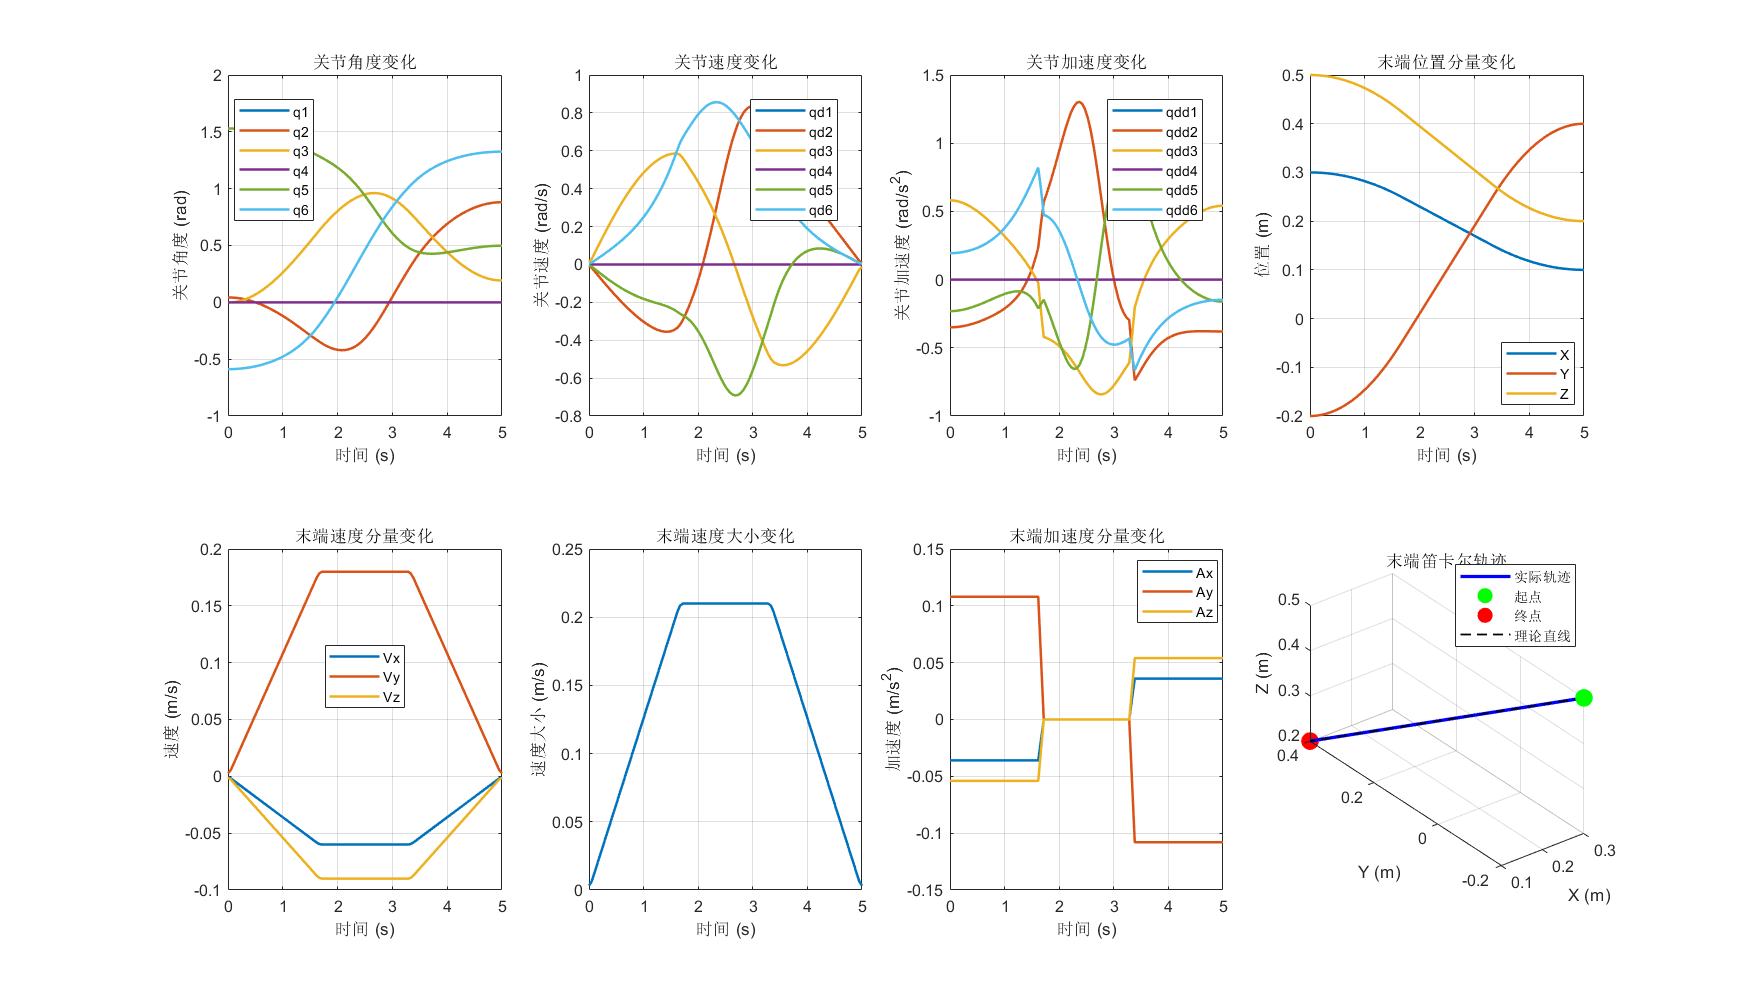

figure('Position', [100, 100, 1400, 800]);

% 1. 关节角度变化曲线
subplot(2,4,1);
plot(t, q_cpline, 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('关节角度 (rad)');
title('关节角度变化');
legend('q1', 'q2', 'q3', 'q4', 'q5', 'q6', 'Location', 'best');
grid on;

% 2. 关节速度变化曲线
subplot(2,4,2);
plot(t, q_cpline_d, 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('关节速度 (rad/s)');
title('关节速度变化');
legend('qd1', 'qd2', 'qd3', 'qd4', 'qd5', 'qd6', 'Location', 'best');
grid on;

% 3. 关节加速度变化曲线
subplot(2,4,3);
plot(t, q_cpline_dd, 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('关节加速度 (rad/s^2)');
title('关节加速度变化');
legend('qdd1', 'qdd2', 'qdd3', 'qdd4', 'qdd5', 'qdd6', 'Location', 'best');
grid on;

% 4. 末端位置分量变化
subplot(2,4,4);
plot(t, pos_cpline, 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('位置 (m)');
title('末端位置分量变化');
legend('X', 'Y', 'Z', 'Location', 'best');
grid on;

% 5. 末端速度分量变化
subplot(2,4,5);
plot(t, vel_cpline, 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('速度 (m/s)');
title('末端速度分量变化');
legend('Vx', 'Vy', 'Vz', 'Location', 'best');
grid on;

% 6. 末端速度大小变化
subplot(2,4,6);
plot(t, vel_magnitude, 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('速度大小 (m/s)');
title('末端速度大小变化');
grid on;

% 7. 末端加速度分量变化
subplot(2,4,7);
plot(t, acc_cpline, 'LineWidth', 1.5);
xlabel('时间 (s)');
ylabel('加速度 (m/s^2)');
title('末端加速度分量变化');
legend('Ax', 'Ay', 'Az', 'Location', 'best');
grid on;

% 8. 末端笛卡尔轨迹（3D视图）
subplot(2,4,8);
plot3(pos_cpline(:,1), pos_cpline(:,2), pos_cpline(:,3), 'b-', 'LineWidth', 2);
hold on;
plot3(pos_cpline(1,1), pos_cpline(1,2), pos_cpline(1,3), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot3(pos_cpline(end,1), pos_cpline(end,2), pos_cpline(end,3), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
% 绘制理论直线
plot3([pos_cpline(1,1), pos_cpline(end,1)], [pos_cpline(1,2), pos_cpline(end,2)], [pos_cpline(1,3), pos_cpline(end,3)], ...
      'k--', 'LineWidth', 1);
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('末端笛卡尔轨迹');
legend('实际轨迹', '起点', '终点', '理论直线', 'Location', 'best');
grid on;
axis equal;

## 机器人运动动画（单独窗口）

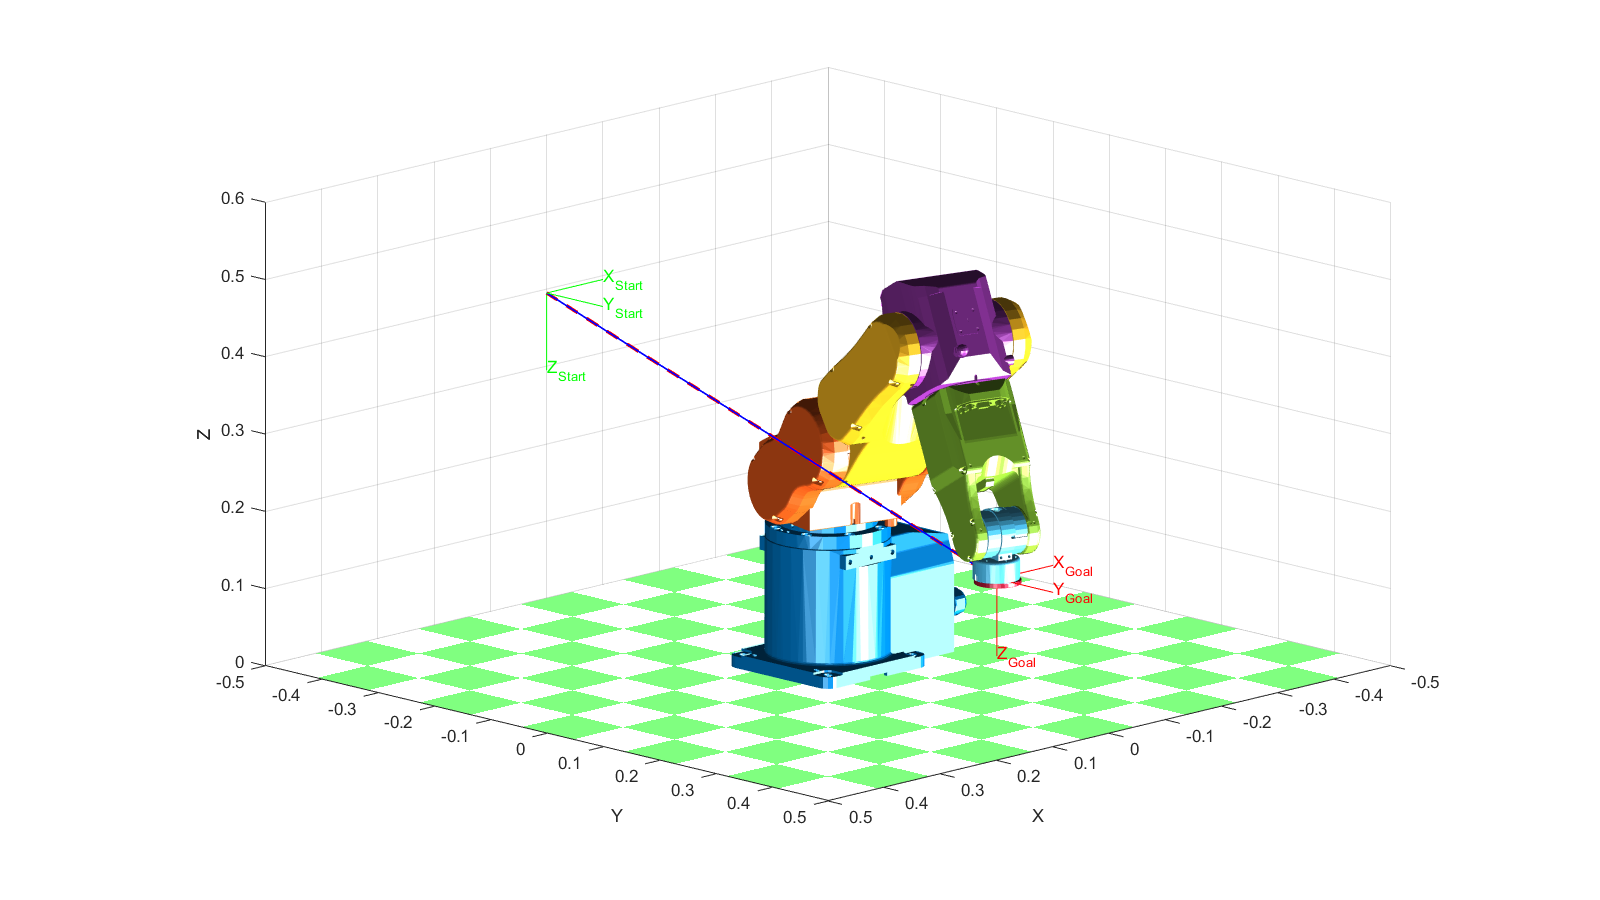

Animate: saving video --> .\videos\cartesion_CP_line.mp4 with profile 'MPEG-4'
Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


% figure('Position', [100, 100, 800, 600]); % 视频质量较低
figure('Position', [100, 100, 1280, 720], 'Name', 'CP直线路径', 'Renderer','opengl'); % RTB直接渲染动画的话，只支持720P，再高会出现画面裁剪
title('CP直线轨迹运动动画');
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
% 绘制目标轨迹
axis(workspace);
p_start = transl(T_start);
p_goal = transl(T_goal);
plot3([p_start(1), p_goal(1)], ...
      [p_start(2), p_goal(2)], ...
      [p_start(3), p_goal(3)], ...
      'r--', 'LineWidth', 2);
hold on;
% 绘制起止点
trplot(T_start, 'color', 'g', 'frame', 'Start', 'length', 0.1);
trplot(T_goal, 'color', 'r', 'frame', 'Goal', 'length', 0.1);
hold on;
% 绘制机械臂动画
light('Position', [1, 1, -1], 'color', 'w'); % 打光，不然机械臂有点暗
light('Position', [1, 1, 1], 'color', 'w'); % 打光，不然机械臂有点暗
EpsonC3.plot3d(q_cpline, 'tilesize', 0.1, 'path', file_path, 'nowrist', 'trail', {'b', 'linewidth', 1}, 'workspace', workspace, 'scale', 0.5, 'fps', 20, ...
    'movie', '.\videos\cartesion_CP_line.mp4');

## 轨迹规划结果评估

fprintf('\n========== CP直线轨迹规划结果 ==========\n');


========== CP直线轨迹规划结果 ==========


fprintf('起始关节角度: [%.3f, %.3f, %.3f, %.3f, %.3f, %.3f] rad\n', q_start);

起始关节角度: [-0.588, 0.043, -0.002, -0.000, 1.530, -0.588] rad


fprintf('目标关节角度: [%.3f, %.3f, %.3f, %.3f, %.3f, %.3f] rad\n', q_goal);

目标关节角度: [1.326, 0.881, 0.192, 0.000, 0.498, 1.326] rad


fprintf('总运动时间: %.2f s\n', t_total);

总运动时间: 5.00 s


fprintf('采样点数: %d\n', t_samples);

采样点数: 100



% 计算最大关节速度
max_qd = max(abs(q_cpline_d), [], 1);
fprintf('\n最大关节速度 (rad/s):\n');


最大关节速度 (rad/s):


for i = 1:6
    fprintf('关节%d: %.3f\n', i, max_qd(i));
end

关节1: 0.857
关节2: 0.835
关节3: 0.585
关节4: 0.000
关节5: 0.691
关节6: 0.857



% 计算最大关节加速度
max_qdd = max(abs(q_cpline_dd), [], 1);
fprintf('\n最大关节加速度 (rad/s²):\n');


最大关节加速度 (rad/s²):


for i = 1:6
    fprintf('关节%d: %.3f\n', i, max_qdd(i));
end

关节1: 0.821
关节2: 1.303
关节3: 0.842
关节4: 0.000
关节5: 0.953
关节6: 0.821



% 末端速度统计
fprintf('\n末端速度统计:\n');


末端速度统计:


fprintf('平均速度: %.3f m/s\n', mean(vel_magnitude));

平均速度: 0.139 m/s


fprintf('最大速度: %.3f m/s\n', max(vel_magnitude));

最大速度: 0.210 m/s


fprintf('最小速度: %.3f m/s\n', min(vel_magnitude(2:end-1))); % 排除端点

最小速度: 0.006 m/s




% 检查关节限位（假设关节限位为±pi）
qlim = repmat([-pi, pi], 6, 1);
fprintf('\n关节限位检查:\n');


关节限位检查:


for i = 1:6
    if any(q_cpline(:,i) < qlim(i,1)) || any(q_cpline(:,i) > qlim(i,2))
        fprintf('警告: 关节%d超出限位范围 [%.2f, %.2f]\n', i, qlim(i,1), qlim(i,2));
    else
        fprintf('关节%d在限位范围内 [%.2f, %.2f]\n', i, qlim(i,1), qlim(i,2));
    end
end

关节1在限位范围内 [-3.14, 3.14]
关节2在限位范围内 [-3.14, 3.14]
关节3在限位范围内 [-3.14, 3.14]
关节4在限位范围内 [-3.14, 3.14]
关节5在限位范围内 [-3.14, 3.14]
关节6在限位范围内 [-3.14, 3.14]



% %% 保存结果
% save('CP_line_trajectory.mat', 'q_cp', 'q_cp_d', 'q_cp_dd', 't', ...
%      'T_start', 'T_goal', 'q_start', 'q_goal', 'pos_cp', 'vel_cp', 'acc_cp');